## Experimento 3 - MP3 Player (Parte 4)

#### Bruno Hashimoto - 10715628

#### Guilherme Fernandes - 10297272

clear;
clc;

addpath('.', 'data', 'functions');
load('data/Analise_Sintese32.mat');

### 4.a) Quantização do sinal

M = 32; % número de filtros
[x, fa] = audioread('data/violino.wav');
x = x';
y = [];

Nbits = 4; %bits

for i=1:M
    vi = filter(PQMF32_Hfilters(i,:), 1, x);
    vi = sub_amostragem(vi, M);
    viq = midtreadQ(vi, Nbits, 1); % quantização

    yi = sobre_amostragem(viq, M);
    yi = filter(PQMF32_Gfilters(i, :), 1, yi);
    y(i, :) = yi;
end

[~, filter_size] = size(PQMF32_Hfilters);
filter_order = filter_size-1 ;
y_sum = sum(y, 1);

% atraso
y_sem_atraso = y_sum(filter_order+1:end);
n_sem_atraso = length(y_sem_atraso);

% SNR
SNR = snr(x(1:n_sem_atraso), y_sem_atraso, 0)

SNR = 10.3308

Escutando-se o som verifica-se que houve distorção no sinal. Em relação a seção anterior, o valor do SNR diminuiu significantemente, em aproximadamente 90%. A diminuição é justificada dado a quantização.

### 4.b) Utilizando transformada Lapped

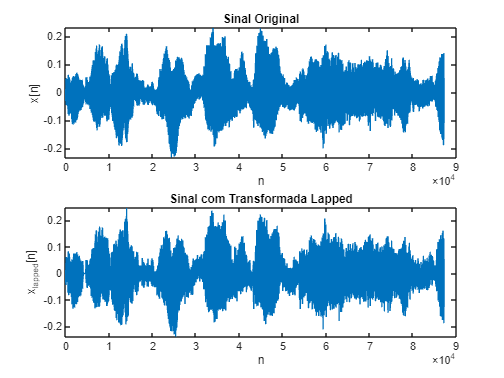

y_lappedQ = lappedQ(x, fa, PQMF32_Hfilters, PQMF32_Gfilters, Nbits);
x_lappedQ = x(filter_size:end-filter_size+1);
n_lapped = length(y_lappedQ);

figure;
subplot(2,1,1);
plot(0:n_lapped-1, x_lappedQ);
xlabel('n');
ylabel('x[n]');
title('Sinal Original');

subplot(2,1,2);
plot(0:n_lapped-1, y_lappedQ);
xlabel('n');
ylabel('x_{lapped}[n]');
title('Sinal com Transformada Lapped');

SNR_lappedQ = snr(x_lappedQ, y_lappedQ, 0)

SNR_lappedQ = 10.3338

Utilizando a transformada Lapped houve pouca melhoria em termos de SNR, o sinal aparenta ter menos distorção, porém a distorção ainda é perceptível.

### 4.c) Lapped com fator de escala

A função **lappedQadap** inclui um fator de escala para quantizar o bloco que é processado durante seu procedimento. Nesse caso, admite-se uma quantização adaptada a cada bloco que está sendo processado.

y_lappedQadap = lappedQadap(x, fa, PQMF32_Hfilters, PQMF32_Gfilters, Nbits);
x_lappedQadap = x(filter_size:end-filter_size);

SNR_lappedQadap = snr(x_lappedQadap, y_lappedQadap, 0)

SNR_lappedQadap = 25.0629

Não apenas o SNR melhorou como também as distorções no sinal são praticamente inaudíveis.

### 4.d) Utilizando lapped Psico

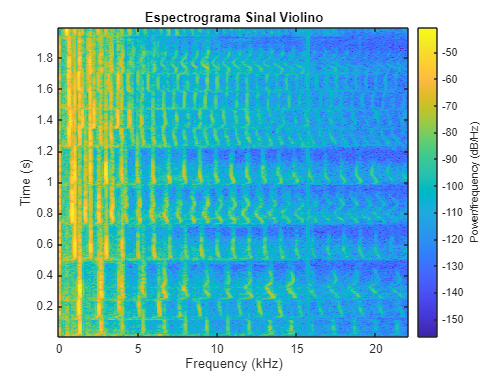

bitrate = 192000; %bits/s
y_lappedPsico = lappedPsico(x, fa, PQMF32_Hfilters, PQMF32_Gfilters, bitrate);
x_lappedPsico = x(filter_size:end-filter_size);

figure;
spectrogram(x, hanning(512), 256, 1024, fa);
title('Espectrograma Sinal Violino');

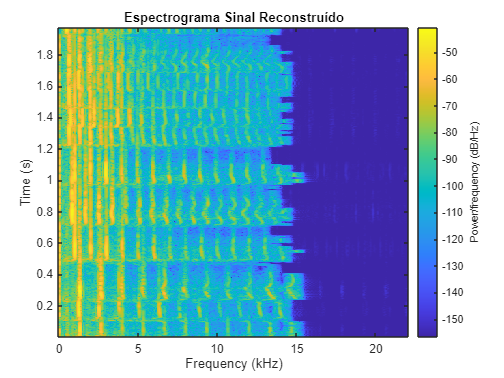

figure;
spectrogram(y_lappedPsico, hanning(512), 256, 1024, fa);
title('Espectrograma Sinal Reconstruído');

SNR_lappedPsico = snr(x_lappedPsico, y_lappedPsico,0)

SNR_lappedPsico = 38.6457

Observa-se novamente uma melhoria no SNR com o método lapped Psico.

### e) Alteração no lapped Psico

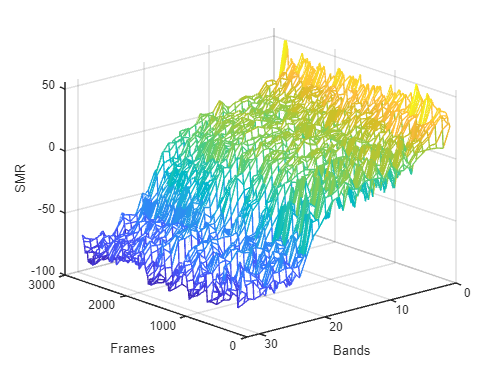

[y_lappedPsico, SMR_mat, Nbits_mat] = lappedPsico(x, fa, PQMF32_Hfilters, PQMF32_Gfilters, bitrate);
frames = 1:12:2736;
M = 1:1:32;
[X,Y] = meshgrid(frames, M);

figure;
mesh(X, Y, SMR_mat');
xlabel('Frames');  
ylabel('Bands');
zlabel('SMR');

view([-131 23])

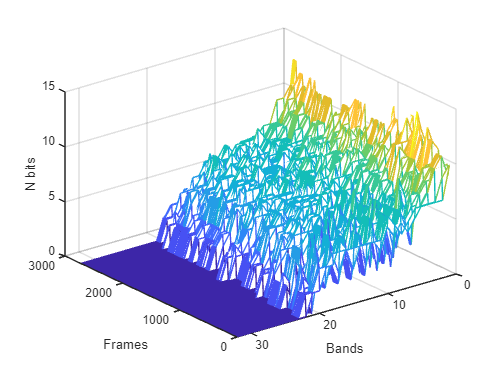

figure;
mesh(X, Y, Nbits_mat');
xlabel('Frames');  
ylabel('Bands');
zlabel('N bits');

view([-128.2 32.0])